## **1- Initialization - Loading and initializing necessary data and variables**

First, the various variables necessary to the training and test of our method are created. 

The SOM-Toolbox is loaded.

warning('off')
addpath(genpath('SOM-Toolbox/')); %Adding the path to the SOM Toolbox

The lists of variable names are determined so that the pigment, depth, and satellite data can be manipulated either separately or together.

%Here we define the various variable names in order to manipulate our data
%more easily
pigment_names = ["total chla", "DVchla", "19hex", "fucox", "perid", "zeax"]; %List of pigment names
sat_names = ["RRS412","RRS443","RRS555","KD490","ZEU","ZHL"]; %List of satellite variable names
depths = ["5.0","8.35","13.92","23.23","38.75","64.63","107.81","179.85","300.0"]; %List of investigated depths
pigment_depths_names = []; %List of depth variables for each pigment
for i=1:length(pigment_names)
    for j=1:length(depths)
        pigment_depths_names = [pigment_depths_names, sprintf("%s_%s",[strrep(strrep(pigment_names(i)," ","_"),"19hex","X19hex"),strrep(depths(j),".","_")])];
    end
end
pigment_depths_sat_names = [pigment_depths_names,sat_names]; %List of all the variables (pigments/depths and satellite) of the dataset
depths = str2double(depths) ;

The data from the whole dataset are loaded in the T_all table, while only the observations contatining less than 50% of missing values are loaded in the T table.

%Loading the datasets
T = readtable('data.csv');
T_all = readtable('data_all.csv');

%Extracting useful data from the datasets before keeping only the wanted
%variables

%Lists of station names, longitude and latitude
stations = T(:,ismember(T.Properties.VariableNames,["combined_station"]));
longitude = T(:,ismember(T.Properties.VariableNames,["long_sat"]));
latitude = T(:,ismember(T.Properties.VariableNames,["lat_sat"]));
%Keeping only the variables needed to train the method
T_all = T_all(:,ismember(T_all.Properties.VariableNames,pigment_depths_sat_names));
T = T(:,ismember(T.Properties.VariableNames,pigment_depths_sat_names));

## **2 - Completion of the pigment data with ITCOMPSOM**

The data loaded previously contains missing values. In this section we use the ITCOMPSOM method to complete the pigment data. First, a SOM is train via the ITCOMPSOM method. The training should take a few minutes.

%ITCOMPSOM training of a SOM map on the incomplete pigment dataset with 10
%iterations and 400 neurons
[map_completion, ~, ~, liste_corr] = itcompsom(T_all(:,ismember(T_all.Properties.VariableNames,pigment_depths_names)),10,400,false);

Missing values in data. Consider using the Imputation SOM (see help)
Missing values in data. Consider using the Imputation SOM (see help)


Then the data is completed using this SOM with the correlation weighted euclidean distance between the observations and the neurons.

%Then the incomplete pigment dataset is completed using the previously trained SOM
[complete,~] = completion_data_itcompsom(map_completion,T(:,ismember(T.Properties.VariableNames,pigment_depths_names)),liste_corr,false);

%Insertion of the completed pigment dataset into the full dataset.
idx = ismember(complete.Properties.VariableNames,T.Properties.VariableNames);
T_completed = T;
T_completed(:,ismember(T_completed.Properties.VariableNames,pigment_depths_names)) = complete(:,idx);

## **3 - PCA pretreatment of the profiles for each pigment**

The completed data is complex and noisy. The second step of the SOM_PCA method is to smooth the pigment profiles using PCAs. For each pigment, a PCA is performed on the 9 corresponding depth variables and each profile coordinates are computed on the PCA axes.

Only the coordinates of the first two axes are kept for each pigment, wich allows the reduction of the dataset dimensions and the smoothing of the profiles. 

axes_per_pigment = [2,2,2,2,2,2]; %List of the number of axes to keep for each of the six pigments

for pigment_idx=1:length(pigment_names)
    
    %Selection of the 9 depth variables associated with the current pigment
    pigment=(pigment_idx-1)*length(depths)+1:(pigment_idx-1)*length(depths)+length(depths);
    data_PCA = T_completed{:,pigment};
    
    %Reduce and center the selected data
    mu = mean(data_PCA); 
    s = std(data_PCA);
    data_PCA = (data_PCA-mu)./s;
    center_parameter(:,pigment_idx)=mu'; %Saving PCA normalization parameters
    scale_parameter(:,pigment_idx)=s'; %Saving PCA normalization parameters
    
    %Performing the PCA on the reduced centered selected data
    [COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(data_PCA,'Centered','off');
    
    %Selecting the wanted number of axes
    nbaxes = axes_per_pigment(pigment_idx);
    nbaxes_cumsum=cumsum(axes_per_pigment);
    %Storing of the profiles coordinates on the selected axes and the variables loadings
    coord(:,nbaxes_cumsum(pigment_idx)-axes_per_pigment(pigment_idx)+1:nbaxes_cumsum(pigment_idx)) = SCORE(:,1:nbaxes);
    loadings(:,nbaxes_cumsum(pigment_idx)-axes_per_pigment(pigment_idx)+1:nbaxes_cumsum(pigment_idx)) = COEFF(:,1:nbaxes);
end

The final experimental dataset containing pigment profiles and satellite variables is stored in the T_PCA table.

T_PCA=[array2table(coord),T(:,55:end)]; % Fusion of the profiles coordinates with the satellite data
loadings=array2table(loadings); % Saved variables loadings for each of the PCAs
scale_parameter=array2table(scale_parameter); % Saved scaling parameters for each of the PCAs
center_parameter=array2table(center_parameter); % Saved centering parameters for each of the PCAs

## **4 - Training of the SOM**

Now that the data has been completed and PCA pretreated, the SOM that will be used for the inversion can be trained on a hexagonal map with 400 neurons. 

[sMap, datanorm, data] = training(T_PCA,400); %Training of the SOM on the T_PCA dataset

Missing values in data. Consider using the Imputation SOM (see help)


The euclidean distance between neurons is visualized in the 'u-mat' representation, and the repartition of the data on the neurons is visualized via the 'hitmap'.

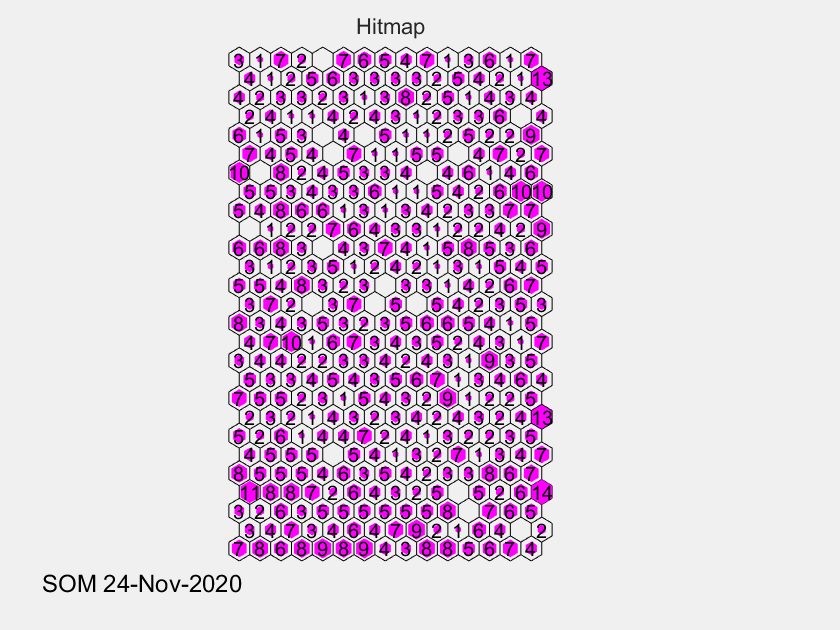

umat_hitmap(sMap, datanorm) %Visualization function fot the U-Matrix and Hitmap

## **5 - Visualization of each component of the neuronal map**

Execute this section to visualize the repartition of each variable on the neuronal map after the reconstruction of the profiles from the saved PCA parameters.

component_maps(sMap,length(pigment_names),'mg.m^-^3',pigment_names,depths,true,loadings,scale_parameter,center_parameter,axes_per_pigment,pigment_depths_names,sat_names)

## **6 - DCM and secondary pigment repartition of the SOM**

In this section, we visualize the DCM depth and the DCM concentration repartition on the neuronal map, after the reconstruction of the profiles from the saved PCA parameters.

%DCM visualizations function
max_chla(sMap,datanorm,depths,pigment_names,true,loadings,scale_parameter,center_parameter,axes_per_pigment,pigment_depths_names,sat_names);

The, the dominating secondary pigment for each neuron and each depth is determined and visualized.

%Dominating pigment at each depth visualization function
dominating_pigment(sMap,datanorm,depths,pigment_names,true,loadings,scale_parameter,center_parameter,axes_per_pigment,pigment_depths_names,sat_names);

## **7 - Example of an inversion**

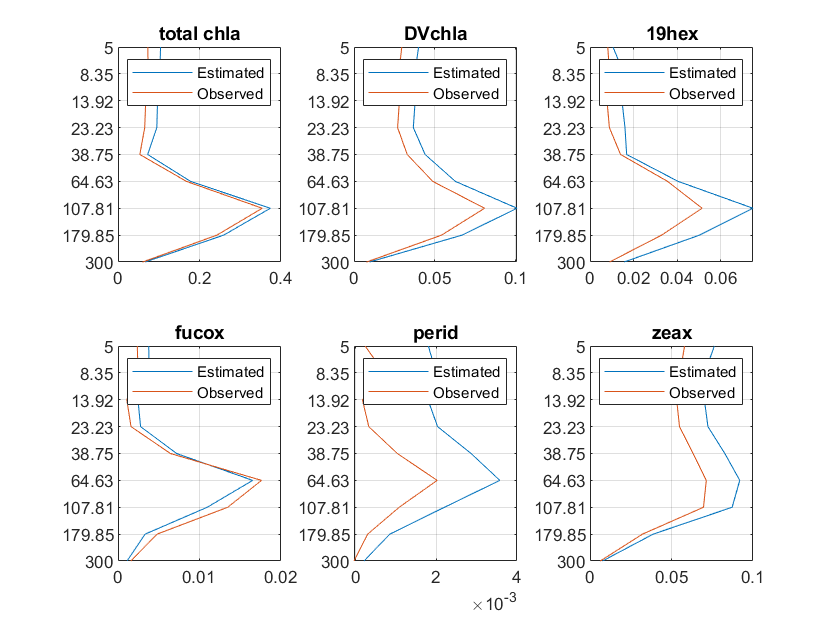

close all
row = 6; %Selection of an observation which has satellite information to invert the pigment data from
observed = T_PCA(row,:); %Storing the observed pigment coordinates
%Creating the observation with masked pigment variables
to_complete = T_PCA(row,:);
to_complete{:,~ismember(T_PCA.Properties.VariableNames,sat_names)}=NaN;
%Inversion of the pigment coordinates from the satellite data and the SOM
[estimated,~]=completion_data(sMap,to_complete,false);

%Reconstruction of the profiles from the saved PCAs' parameters
[estimated,observed]=reconstruction(observed{:,:},estimated{:,:},depths,pigment_names,nbaxes_cumsum,axes_per_pigment,loadings,center_parameter,scale_parameter);

%Plotting the estimated vs observed profile for each pigment of the
%observation
for i=1:length(pigment_names)
    pigment=(i-1)*length(depths)+1:(i-1)*length(depths)+length(depths);
    subplot(2,3,i);
    plot(estimated(:,pigment),[1:9])
    hold on
    plot(observed(:,pigment),[1:9])
    yticklabels(depths);
    yticks([1:9])
    ylim([1,9]);
    set(gca,'Ydir','reverse')
    grid on
    box on
    legend(["Estimated","Observed"])
    title(pigment_names(i))
end

***----------------------------------------------------------------------------------------------***

***                                     K-FOLD VALIDATION***

***----------------------------------------------------------------------------------------------***

The following section contains the code to run the k-fold validation on the pretreated T_PCA dataset. The k-fold validation parameters are pre-set (in order : the used dataset: T_PCA, the number of folds: 10, the number of pigment variables, the selected satellite variables for the inversion, the number of neurons of the SOM: 400). You can change the number of folds but be aware that the runtime for each fold is a few seconds and so the section can take a long time to execute if the number of folds goes above 50.

%k-fold validation function. 
[~, estimated, observed, bmus, idx] = validation_k_fold(T_PCA,10,sum(axes_per_pigment),["RRS412","RRS443","RRS555","KD490","ZEU","ZHL"],400);

%Reconstruction of the profiles from the saved PCA parameters
[estimated,observed]=reconstruction(observed,estimated,depths,pigment_names,nbaxes_cumsum,axes_per_pigment,loadings,center_parameter,scale_parameter);

The results of the k-fold validation are then displayed for each pigment, each depth and the mean by profiles are displayed at the top of the figure.

for i=1:length(pigment_names)
       
    %Selection of the data associated with the current pigment
    X=estimated(:,(i-1)*length(depths)+1:(i-1)*length(depths)+length(depths));
    Y=observed(:,(i-1)*length(depths)+1:(i-1)*length(depths)+length(depths));
    
    %Computing the profiles' mean R² and mean Spearman correlation 
    R2_list=[];
    corr_list=[];
    for l = 1:size(X,1)
        mdl = fitlm(X(l,:),Y(l,:));
        corr_list = [corr_list,corr(X(l,:)',Y(l,:)','Type','Spearman')];
        R2 = mdl.Rsquared.Ordinary;
        R2_list = [R2_list,R2];
    end
    R2_mean=nanmean(R2_list);
    corr_mean=nanmean(corr_list);
    
    sprintf('%s, Spearman = %.2f, R² = %.2f',[pigment_names(i),corr_mean,R2_mean])
    pause
    'Execution paused. Hit any key to continue...'
    close all
end

***----------------------------------------------------------------------------------------------***

***                      TEST ON THE BIOSOPE TRAJECTORY***

***----------------------------------------------------------------------------------------------***

The following section tests the method on the Biosope trajectory from the T_PCA dataset. First, the data is extracted from the T_PCA dataset using the stations name.

non_smoothed_biosope = readtable('data_bodc.csv');
stations_biosope = unique(non_smoothed_biosope(:,9));
stations_biosope = stations_biosope(ismember(stations_biosope,stations),:);
T_PCA_biosope = T_PCA(ismember(stations,stations_biosope),:);

The non-smoothed and smoothed data are stored in tables.

T_non_smoothed_biosope = T_completed(ismember(stations,stations_biosope),:);
observed = T_PCA_biosope{:,1:sum(axes_per_pigment)};

Then the pigment coordinates are masked and then completed using the previously trained SOM. 

T_PCA_biosope{:,~ismember(T_PCA_biosope.Properties.VariableNames,sat_names)} = NaN ;

[T_inverted_biosope,~] = completion_data(sMap, T_PCA_biosope, false);

estimated = T_inverted_biosope{:,1:sum(axes_per_pigment)};

The pigment profiles are then reconstructed from the saved PCA parameters.

[estimated,observed]=reconstruction(observed,estimated,depths,pigment_names,nbaxes_cumsum,axes_per_pigment,loadings,center_parameter,scale_parameter);

Then the profiles are plotted for the inverted estimated data, smoothed observed data, non smoothed observed data and the difference between estimated and observed. .

%Sorting all the tables depending on the ascending longitude
longitude_biosope = longitude(ismember(stations,stations_biosope),:);
[longitude_biosope,I]=sort(longitude_biosope{:,:});
longitude_biosope = round(longitude_biosope,2);
estimated = estimated(I,:);
observed = observed(I,:);
T_non_smoothed_biosope = T_non_smoothed_biosope(I,:);

mask = isnan(estimated); %Storing the NaN values to plot them in gray
diff = estimated-observed;
name='biosope'

name = 'biosope'

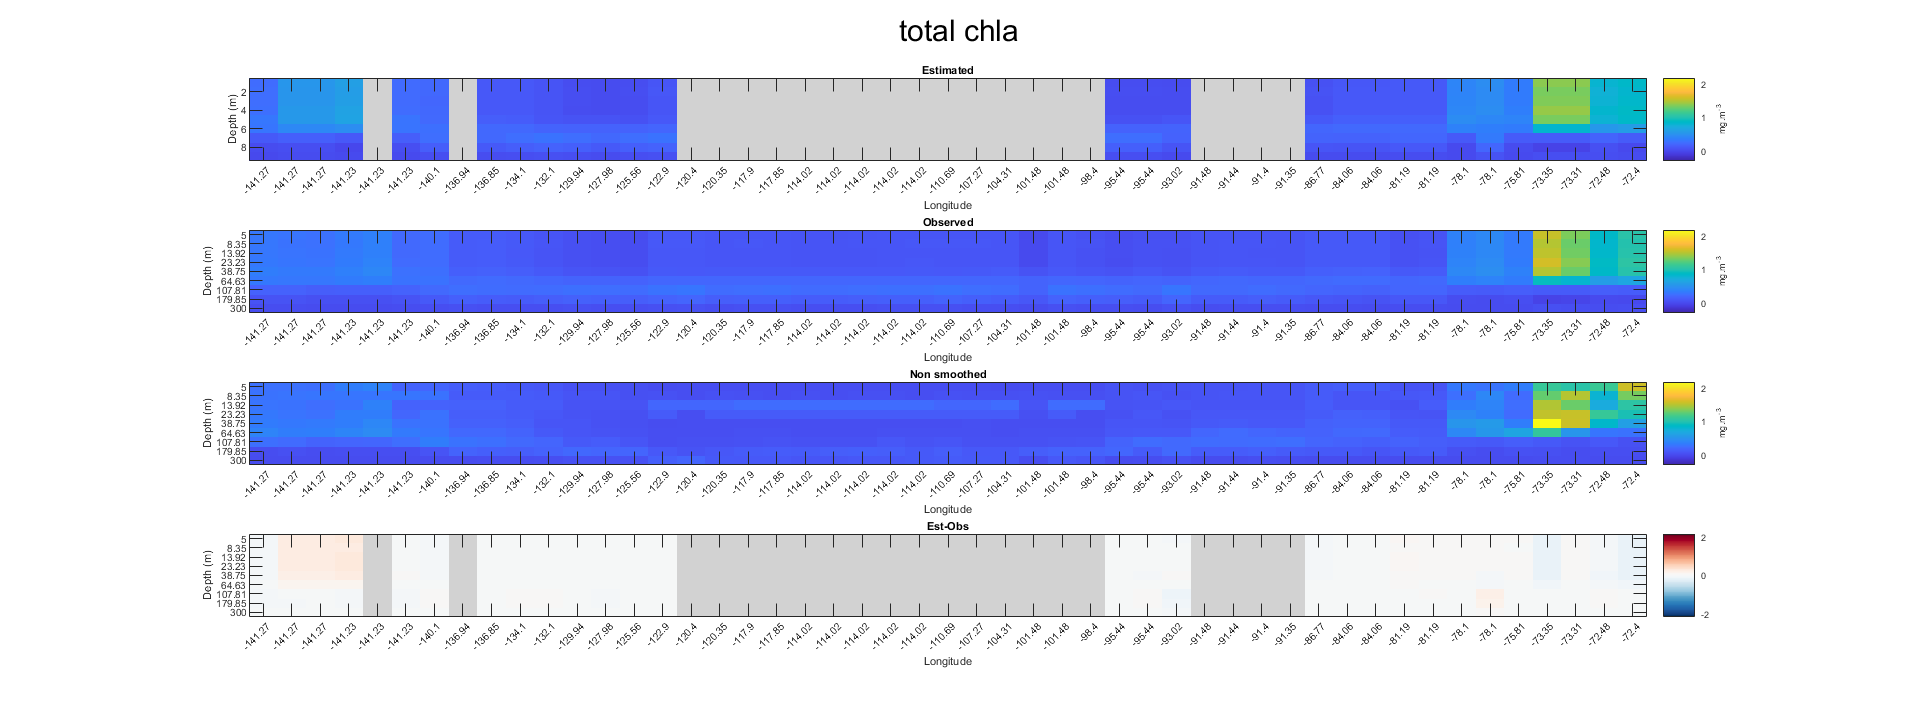

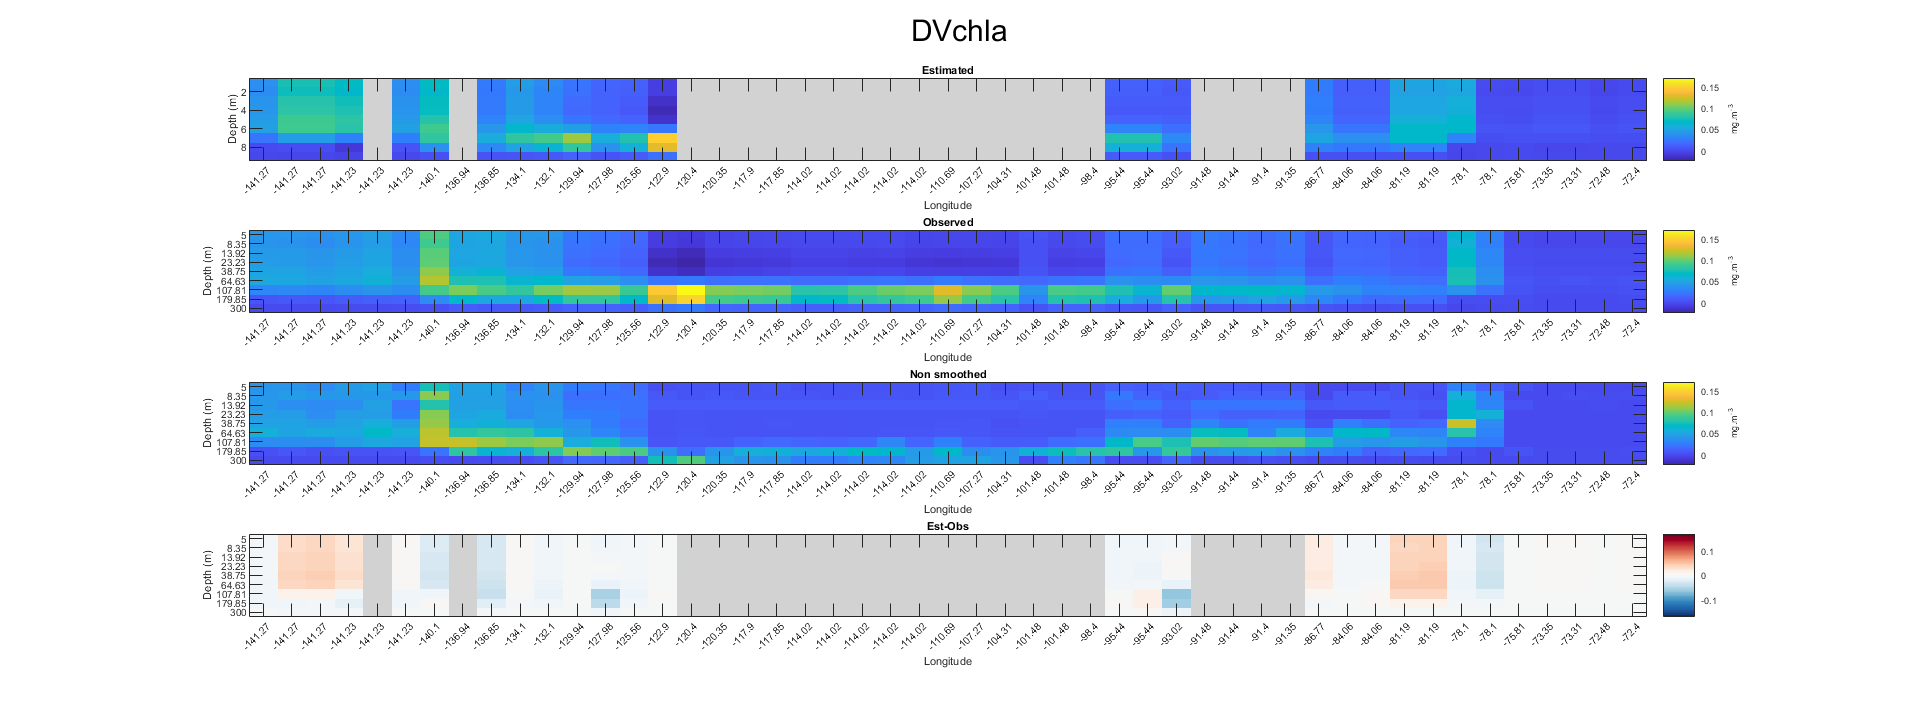

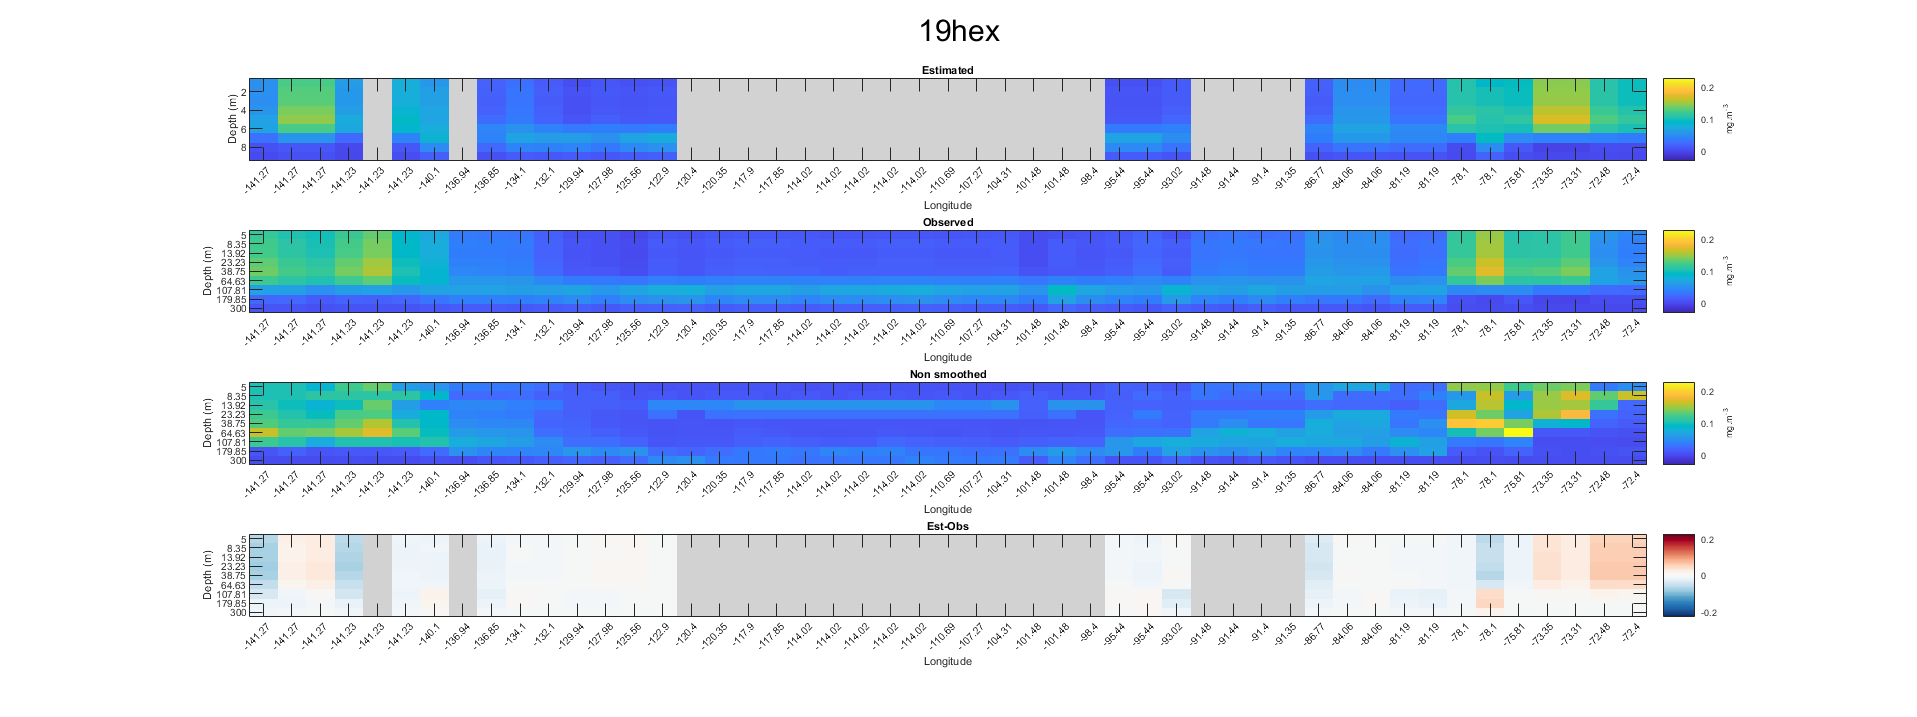

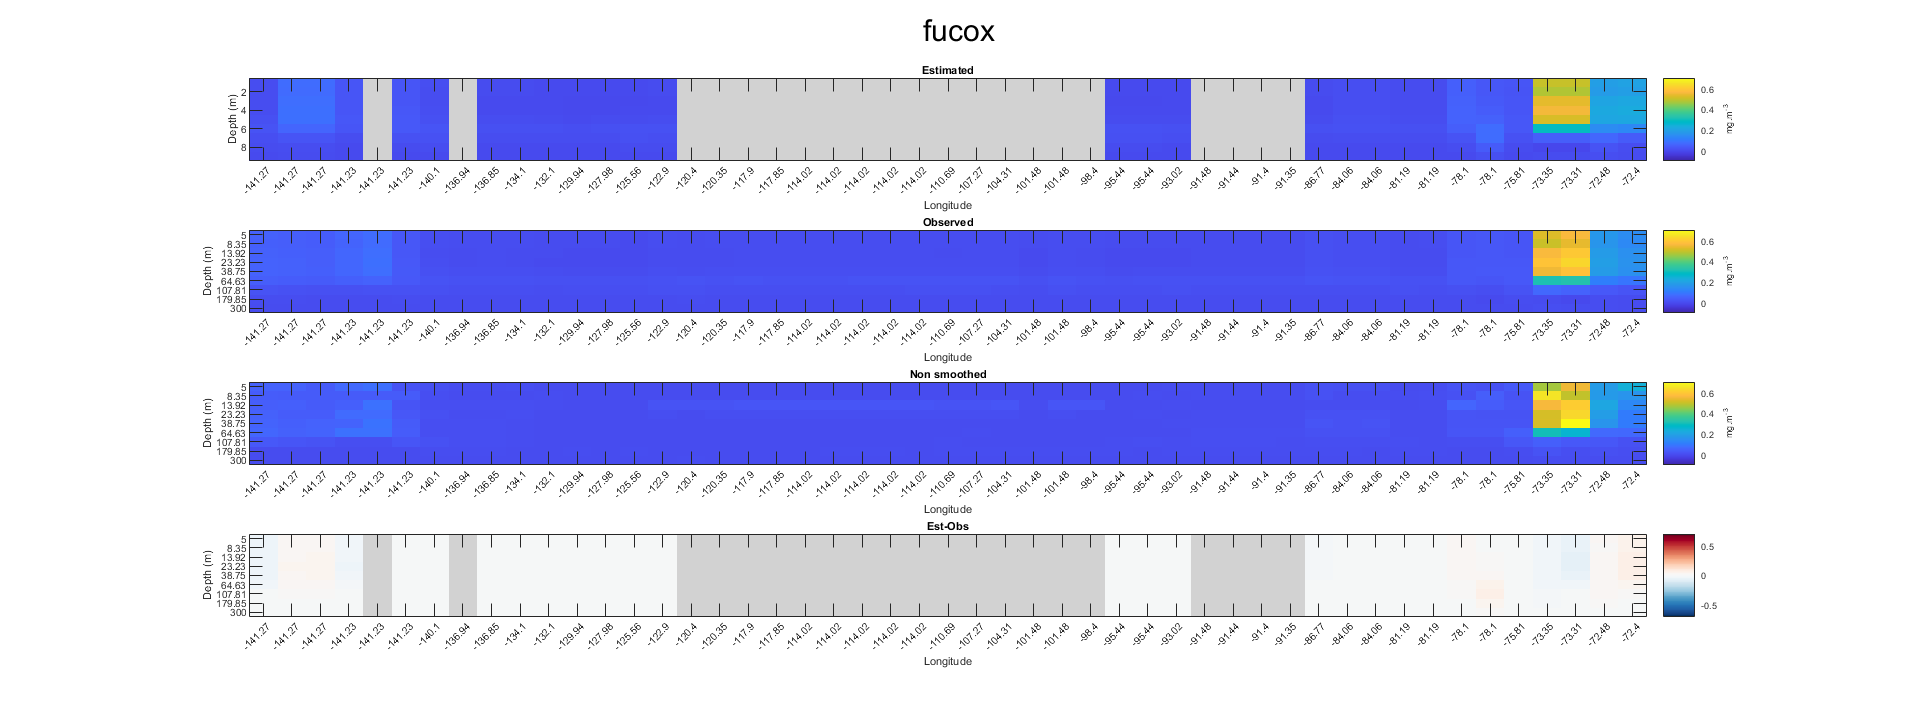

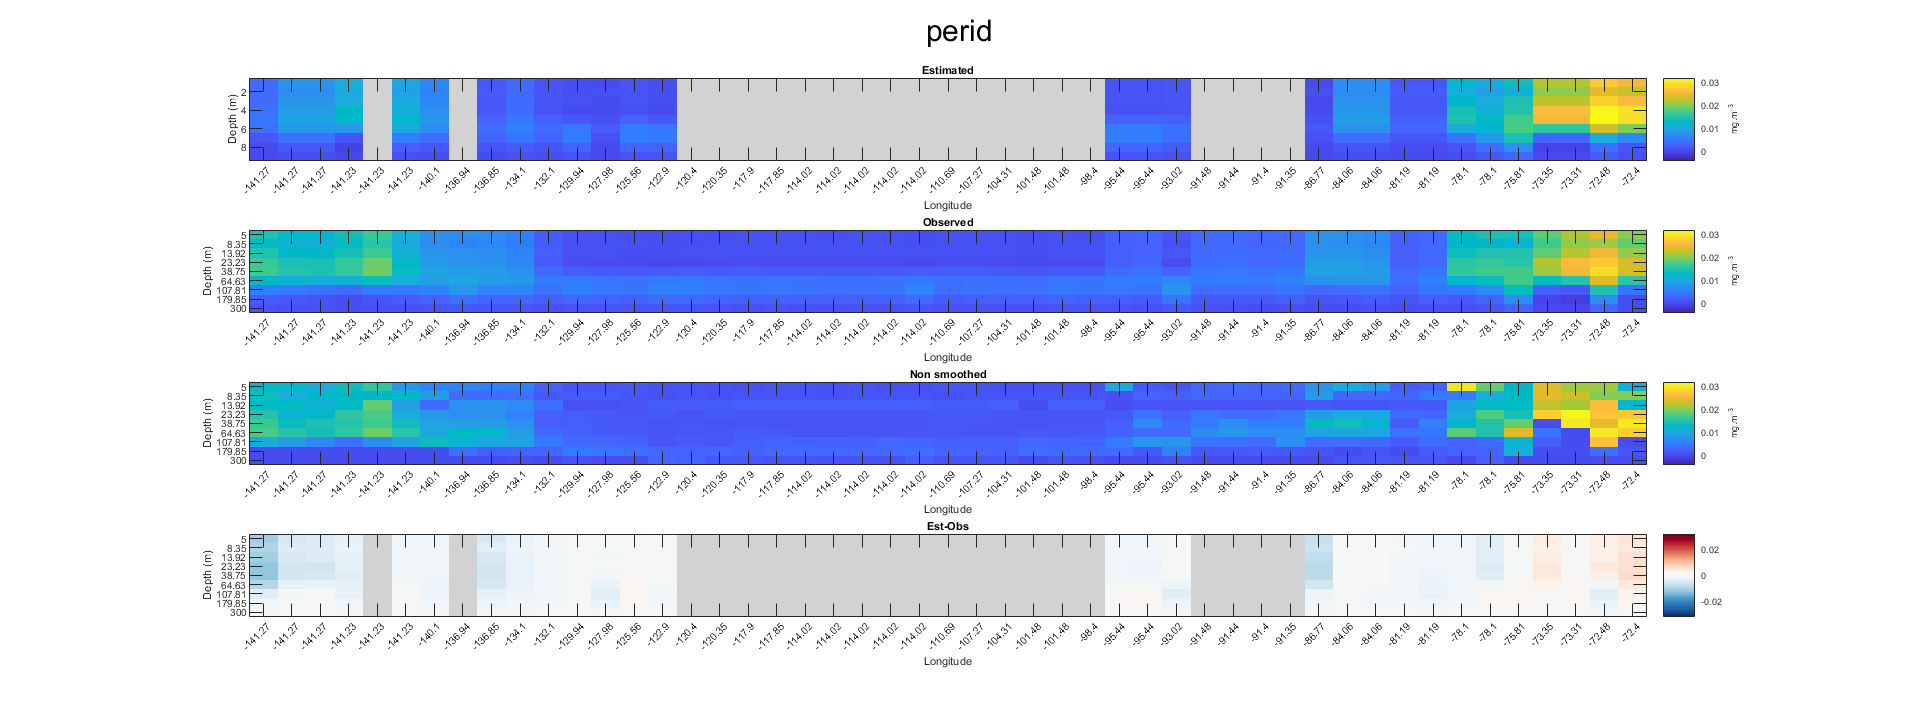

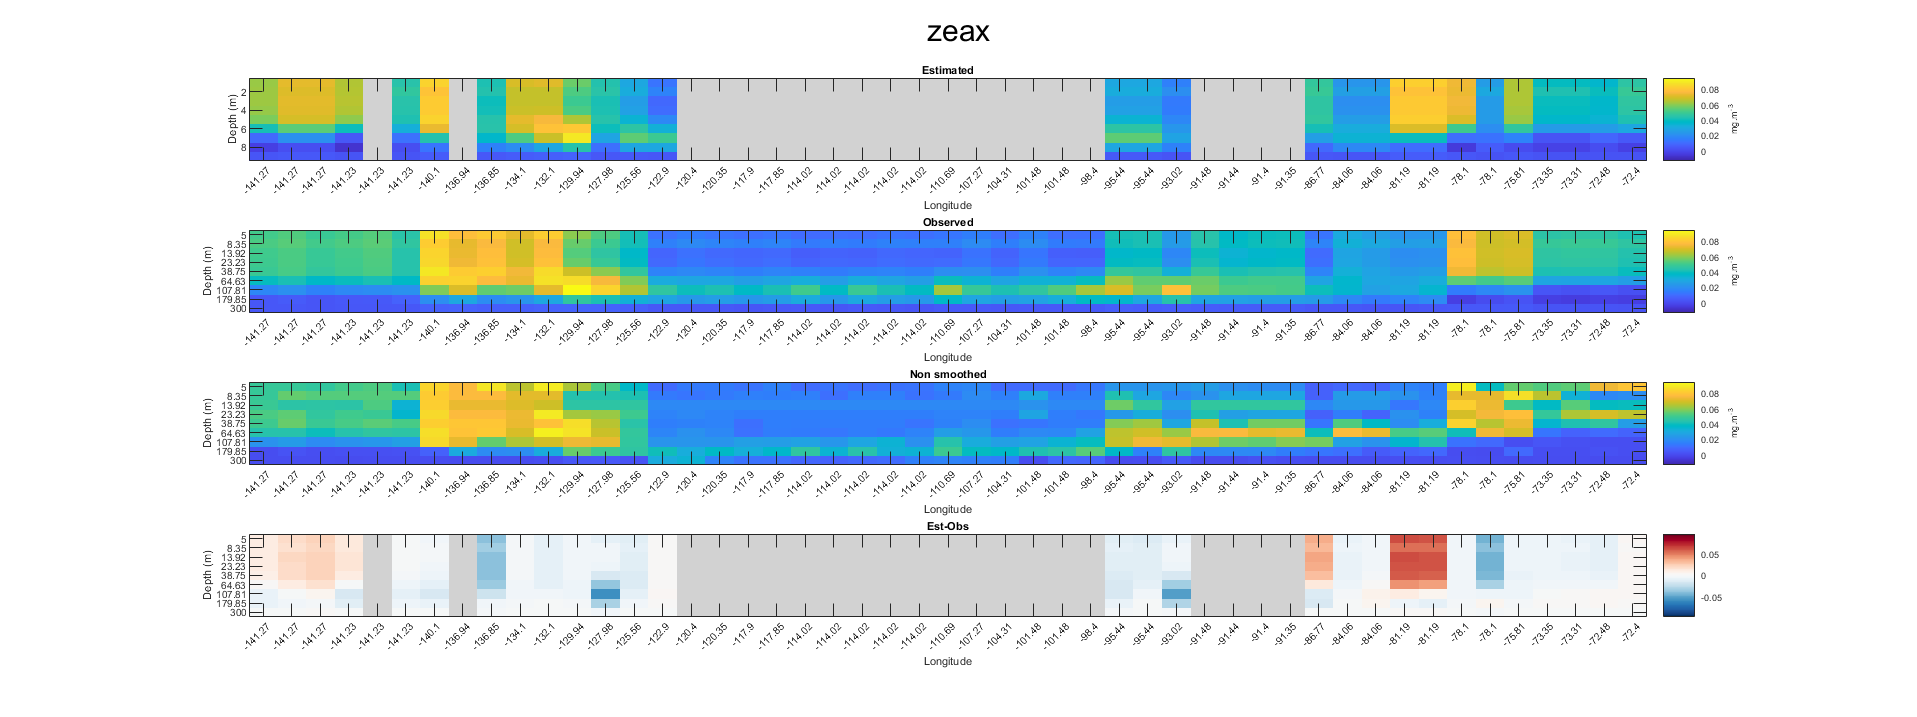


for i=1:length(pigment_names)

    pigment = (i-1)*length(depths)+1:(i-1)*length(depths)+length(depths);
    value_nan=max(max(max(estimated(:,pigment),[],'all'),max(observed(:,pigment),[],'all')),max(T_non_smoothed_biosope{:,pigment},[],'all'))/7; % Value to plot the NaN in gray
    estimated(mask(:,pigment))=-value_nan;
    
    figure('units','normalized','outerposition',[0 0 1 1])
    %Plot of the estimated data
    ax(1)=subplot(4,1,1);
    set(gcf, 'Units', 'Inches', 'Position', [0, 0, 15, 5], 'PaperUnits', 'Inches', 'PaperSize', [15, 5])
    imagesc(estimated(:,pigment)')
    shading flat
    title('Estimated')
    xlabel('Longitude')
    ylabel('Depth (m)')
    caxis([-value_nan,max(max(max(estimated(:,pigment),[],'all'),max(observed(:,pigment),[],'all')),max(T_non_smoothed_biosope{:,pigment},[],'all'))])
    hold on
    xticklabel = get(gca,'XTickLabel');
    set(gca,'XTickLabel',xticklabel,'fontsize',5)
    xtickangle(45)
    xticks([1:size(longitude_biosope,1)])
    xticklabels(string(longitude_biosope))
    set(gca,'Ydir','reverse')
    C1=colorbar;
    C1.Label.String ='mg.m^-^3';
    colormap(ax(1),[0.827,0.827,0.827;parula])
    %Plot of the observed smoothed data
    ax(2)=subplot(4,1,2);
    imagesc(observed(:,pigment)','AlphaData',~isnan(observed(:,pigment)'));
    shading flat
    title('Observed')
    xlabel('Longitude')
    ylabel('Depth (m)')
    caxis([-value_nan,max(max(max(estimated(:,pigment),[],'all'),max(observed(:,pigment),[],'all')),max(T_non_smoothed_biosope{:,pigment},[],'all'))])
    xticklabel = get(gca,'XTickLabel');
    set(gca,'XTickLabel',xticklabel,'fontsize',5)
    xtickangle(45)
    xticks([1:size(longitude_biosope,1)])
    xticklabels(string(longitude_biosope))
    yticks([1:9])
    yticklabels(string(depths'))
    set(gca,'Ydir','reverse')
    C2=colorbar;
    C2.Label.String ='mg.m^-^3';
    colormap(ax(2),parula)
    %Plot of the non smoothed observed data
    ax(3)=subplot(4,1,3);
    imagesc(T_non_smoothed_biosope{:,pigment}','AlphaData',~isnan(T_non_smoothed_biosope{:,pigment}'));
    shading flat
    title('Non smoothed')
    caxis([-value_nan,max(max(max(estimated(:,pigment),[],'all'),max(observed(:,pigment),[],'all')),max(T_non_smoothed_biosope{:,pigment},[],'all'))])
    xlabel('Longitude')
    ylabel('Depth (m)')
    colormap(ax(3),parula)
    xticklabel = get(gca,'XTickLabel');
    set(gca,'XTickLabel',xticklabel,'fontsize',5)
    xtickangle(45)
    xticks([1:size(longitude_biosope,1)])
    xticklabels(string(longitude_biosope))
    yticks([1:9])
    yticklabels(string(depths'))
    set(gca,'Ydir','reverse')
    C3=colorbar;
    C3.Label.String ='mg.m^-^3';
    %Plot of the difference between estimated and observed
    ax(4)=subplot(4,1,4);
    lim=max(max(max(estimated(:,pigment),[],'all'),max(observed(:,pigment),[],'all')),max(T_non_smoothed_biosope{:,pigment},[],'all'));
    diff(mask(:,pigment))=-lim-0.0001;
    imagesc(diff(:,pigment)');
    shading flat
    title('Est-Obs')
    xlabel('Longitude')
    ylabel('Depth (m)')
    caxis([-lim-0.0001,lim])
    colormap(ax(4),[0.827,0.827,0.827;flipud(brewermap(100,'RdBu'))])
    colorbar
    xticklabel = get(gca,'XTickLabel');
    set(gca,'XTickLabel',xticklabel,'fontsize',5)
    xtickangle(45)
    xticks([1:size(longitude_biosope,1)])
    xticklabels(string(longitude_biosope))
    yticks([1:9])
    yticklabels(string(depths'))
    set(gca,'Ydir','reverse')

    sgtitle(pigment_names(i));
    str = sprintf('%s_profiles_%s.eps',name,pigment_names(i));
    saveas(gcf,str,'epsc')

end

***----------------------------------------------------------------------------------------------***

***                 TEST ON TEMPORAL DATA FOR ONE LOCATION***

***----------------------------------------------------------------------------------------------***

The following section tests the method on satellite data for one location. The weekly satellite data from the six pixels around the location and included in a table with the right dimensions filled with NaN values where the pigment coordinates should be inverted.

pixeldata = readtable('pixelspoints.csv');
pixelweek = pixeldata(:,1:2);
pixeldata = pixeldata(:,ismember(pixeldata.Properties.VariableNames,sat_names));
T_temp = table('Size',[size(pixeldata,1),size(T_PCA,2)],'VariableTypes',repmat("double",[1,size(T_PCA,2)]),'VariableNames',T_PCA.Properties.VariableNames);
T_temp{:,:}=NaN;
T_temp(:,ismember(T_temp.Properties.VariableNames,pixeldata.Properties.VariableNames)) = pixeldata;

The pigment coordinates in the PCAs are inverted from the satellite data and then the pigment profiles are reconstructed from the saved PCAs parameters.

[completed,~] = completion_data(sMap, T_temp,false);
T_temp(:,1:sum(axes_per_pigment)) = completed(:,1:sum(axes_per_pigment));
estimated = T_temp{:,1:sum(axes_per_pigment)};
[estimated,~]= reconstruction(zeros(size(estimated)),estimated,depths,pigment_names,nbaxes_cumsum,axes_per_pigment,loadings,center_parameter,scale_parameter);

The inverted data for the 6 pixels are then averaged for each week.

mean_temp=repmat(NaN,[46,54]);
for week=1:46
    mean_temp(week,:)=nanmean(estimated(week:46:1656,:));
end
X = mean_temp;
date = [1:46];

The Pigments' Functional Types (PFTs) are computed from empirical coefficients from the litterature.

coeff = [0.74;1.27;1.41;1.41;0.86] ;

chla=X(:,1:9);
dvchla=X(:,10:18);
x19hex=X(:,19:27);
fucox=X(:,28:36);
perid=X(:,37:45);
zeax=X(:,46:54);

[~,diatoms,~,prok,~,hapt]=PFT(chla,dvchla,x19hex,fucox,perid,zeax,coeff);

Due to the use of empirical retlationships from the litterature, the values of PFTs are set to negative (to be plotted as a NaN) when the Chla value is less than 0.1 mg.m-3.

mask= diatoms>1 | X(:,1:9)<=0.1;
diatoms(mask)=-0.01;
mask= prok>1 | X(:,1:9)<=0.1;
prok(mask)=-0.01;
mask= hapt>1 | X(:,1:9)<=0.1;
hapt(mask)=-0.01;
max_all = max([diatoms,prok,hapt],[],'all');

Then each PFT's profiles is plotted alongside of its corresponding diagnostic pigment's profiles.

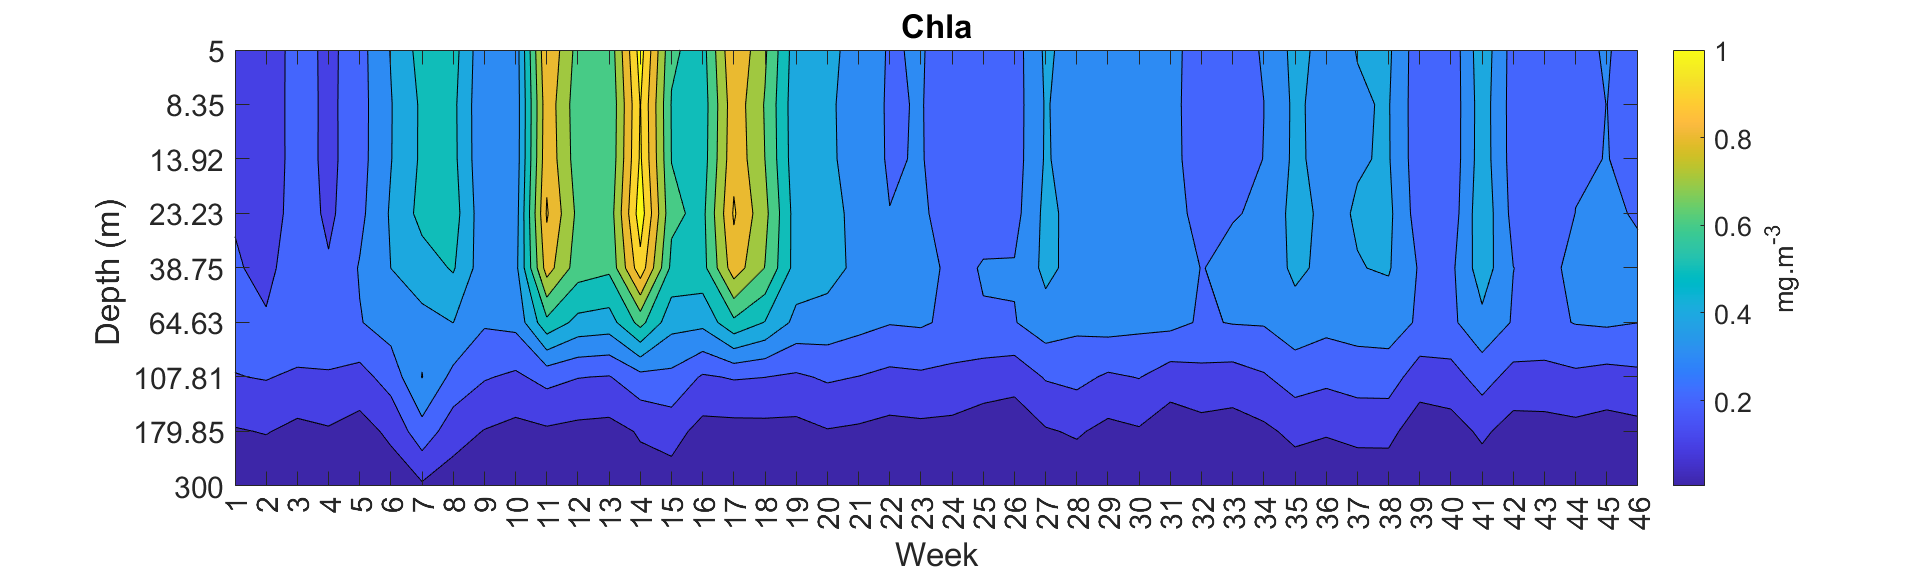

%---Chl-A--------------------------------------------------------------------

ax(1)=figure;
contourf(chla')
C1=colorbar;
C1.Label.String ='mg.m^-^3';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',15)
xtickangle(90)
xticks(date)
xticklabels(date)
yticks([1:9])
yticklabels(string(depths'))
set(gca,'Ydir','reverse')
xlabel("Week")
ylabel("Depth (m) ")
title('Chla')
colormap(ax(1),parula)
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 20, 4], 'PaperUnits', 'Inches', 'PaperSize', [20, 15])
str = "chla_temp.eps";
saveas(gcf,str,'epsc')

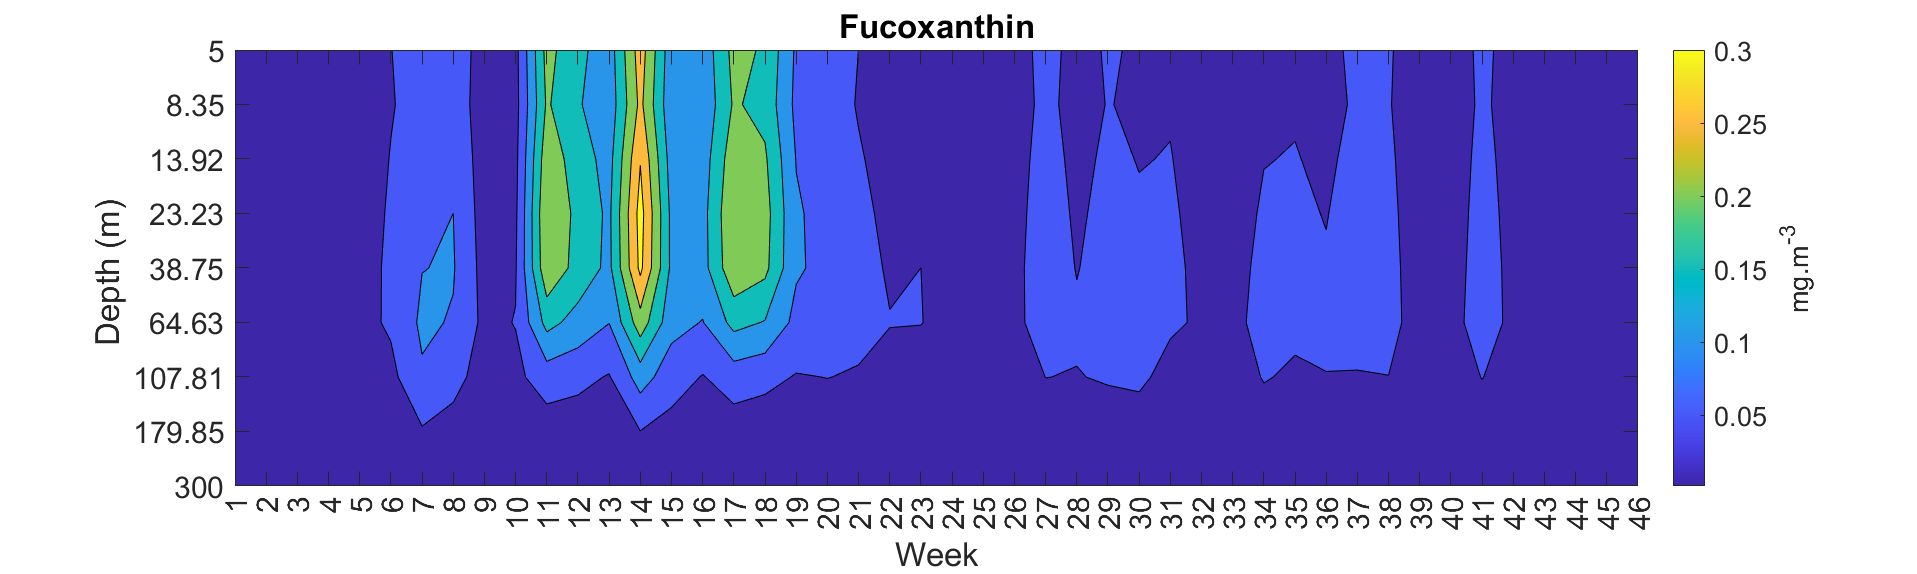


%------------DIATOMS----------------------------------------------------------------

ax(1)=figure;
contourf(fucox')
title('Fucoxanthin')
C1=colorbar;
C1.Label.String ='mg.m^-^3';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',15)
xtickangle(90)
xticks(date)
xticklabels(date)
yticks([1:9])
yticklabels(string(depths'))
set(gca,'Ydir','reverse')
xlabel("Week")
ylabel("Depth (m) ")
colormap(ax(1),parula)
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 20, 4], 'PaperUnits', 'Inches', 'PaperSize', [20, 15])
str = "fucox_temp.eps";
saveas(gcf,str,'epsc')

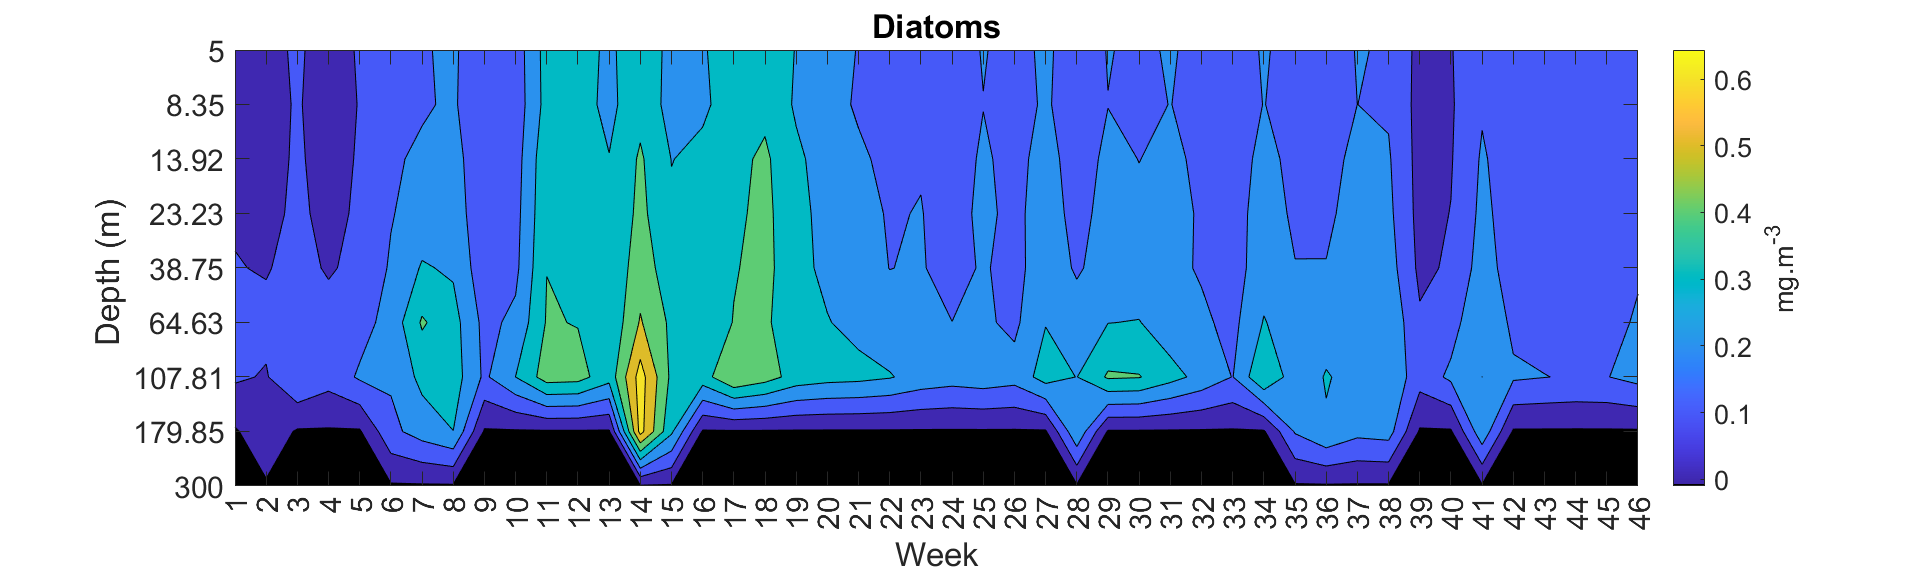


ax(2)=figure;
contourf(diatoms')
title('Diatoms')
C1=colorbar;
C1.Label.String ='mg.m^-^3';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',15)
xtickangle(90)
xticks(date)
xticklabels(date)
yticks([1:9])
yticklabels(string(depths'))
set(gca,'Ydir','reverse')
xlabel("Week")
ylabel("Depth (m) ")
caxis([-0.01,max_all]);
colormap(ax(2),[0,0,0;parula])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 20, 4], 'PaperUnits', 'Inches', 'PaperSize', [20, 15])

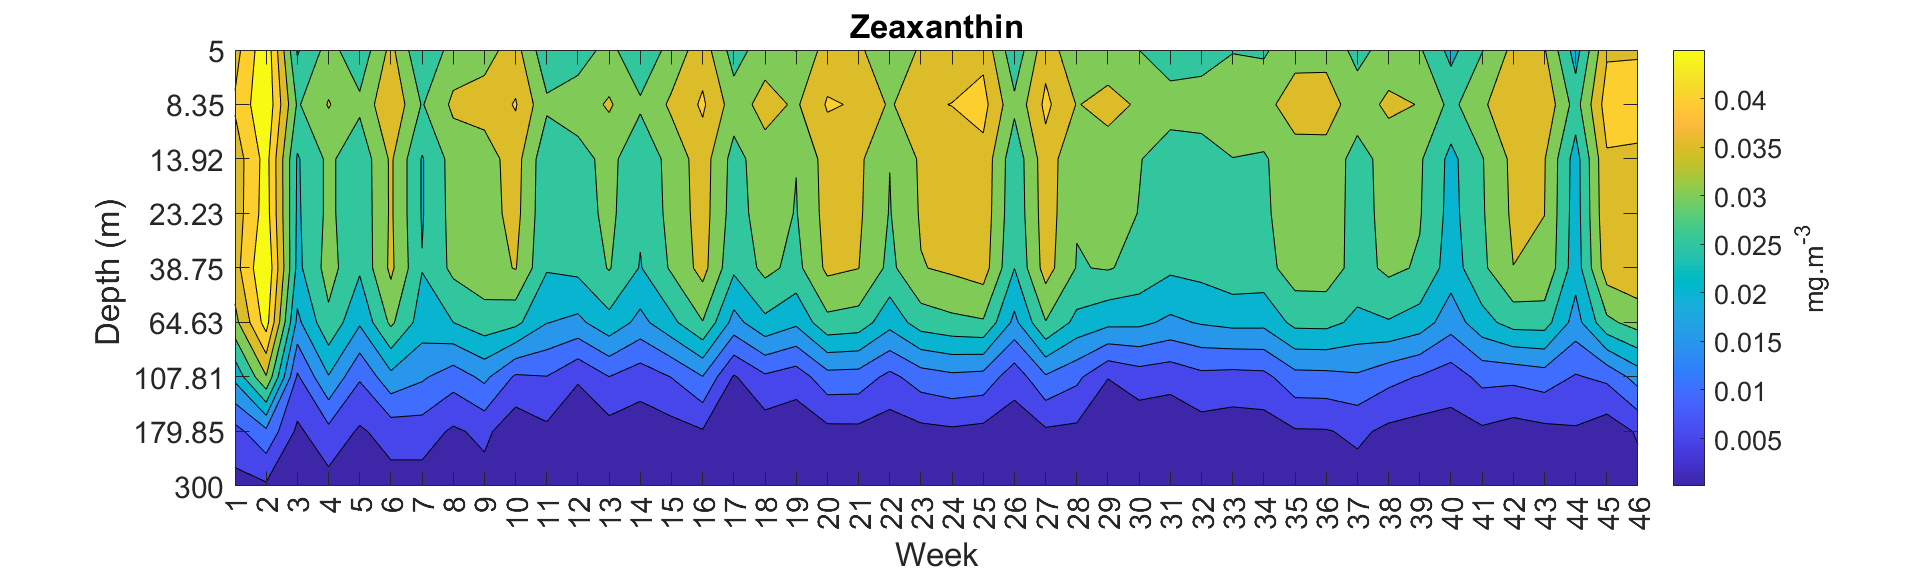


%----------PROKARYOTES--------------------------------------

ax(1)=figure;
contourf(zeax')
title('Zeaxanthin')
C1=colorbar;
C1.Label.String ='mg.m^-^3';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',15)
xtickangle(90)
xticks(date)
xticklabels(date)
yticks([1:9])
yticklabels(string(depths'))
set(gca,'Ydir','reverse')
xlabel("Week")
ylabel("Depth (m) ")
colormap(ax(1),parula)
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 20, 4], 'PaperUnits', 'Inches', 'PaperSize', [20, 15])
str = "zeax_temp.eps";
saveas(gcf,str,'epsc')

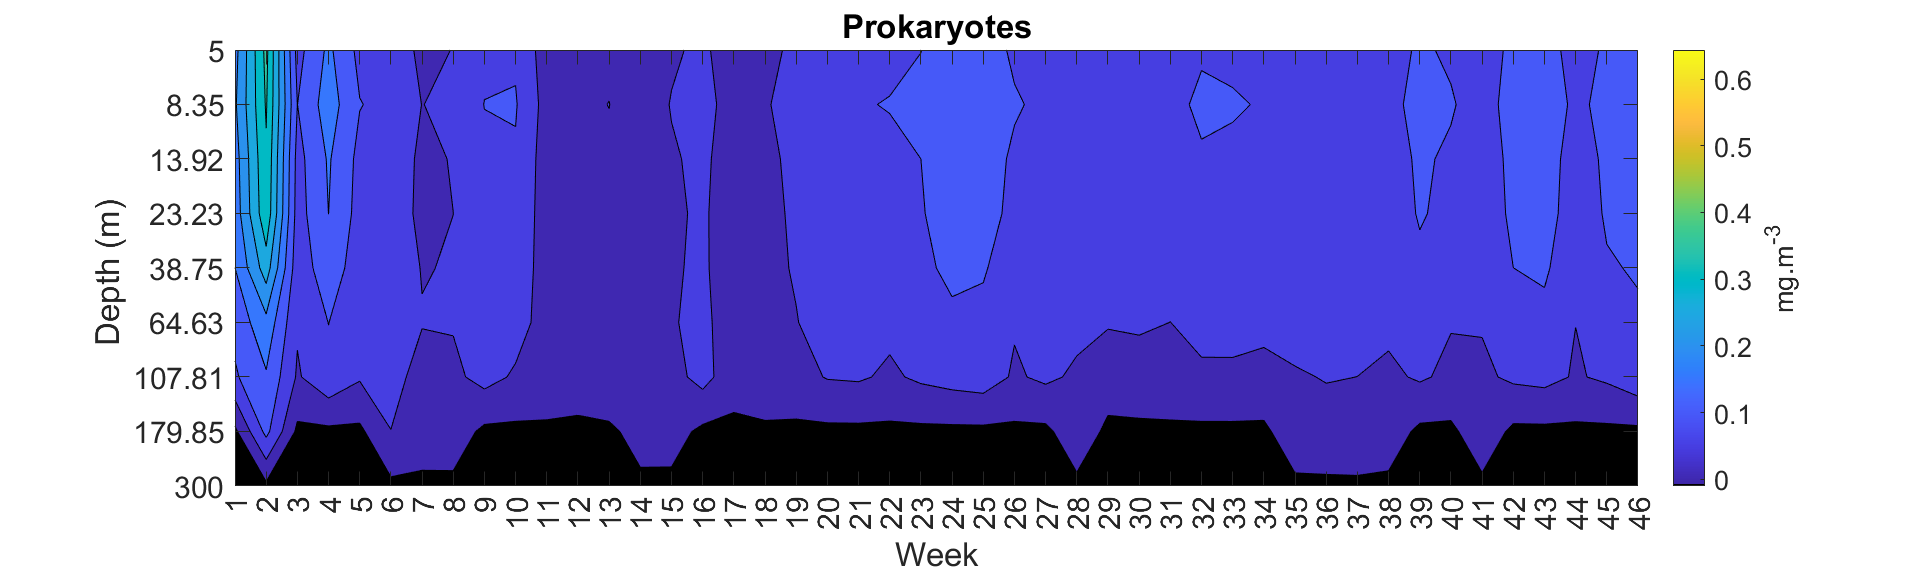


ax(2)=figure;
contourf(prok')
title('Prokaryotes')
C1=colorbar;
C1.Label.String ='mg.m^-^3';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',15)
xtickangle(90)
xticks(date)
xticklabels(date)
yticks([1:9])
yticklabels(string(depths'))
set(gca,'Ydir','reverse')
xlabel("Week")
ylabel("Depth (m) ")
caxis([-0.01,max_all]);
colormap(ax(2),[0,0,0;parula])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 20, 4], 'PaperUnits', 'Inches', 'PaperSize', [20, 15])

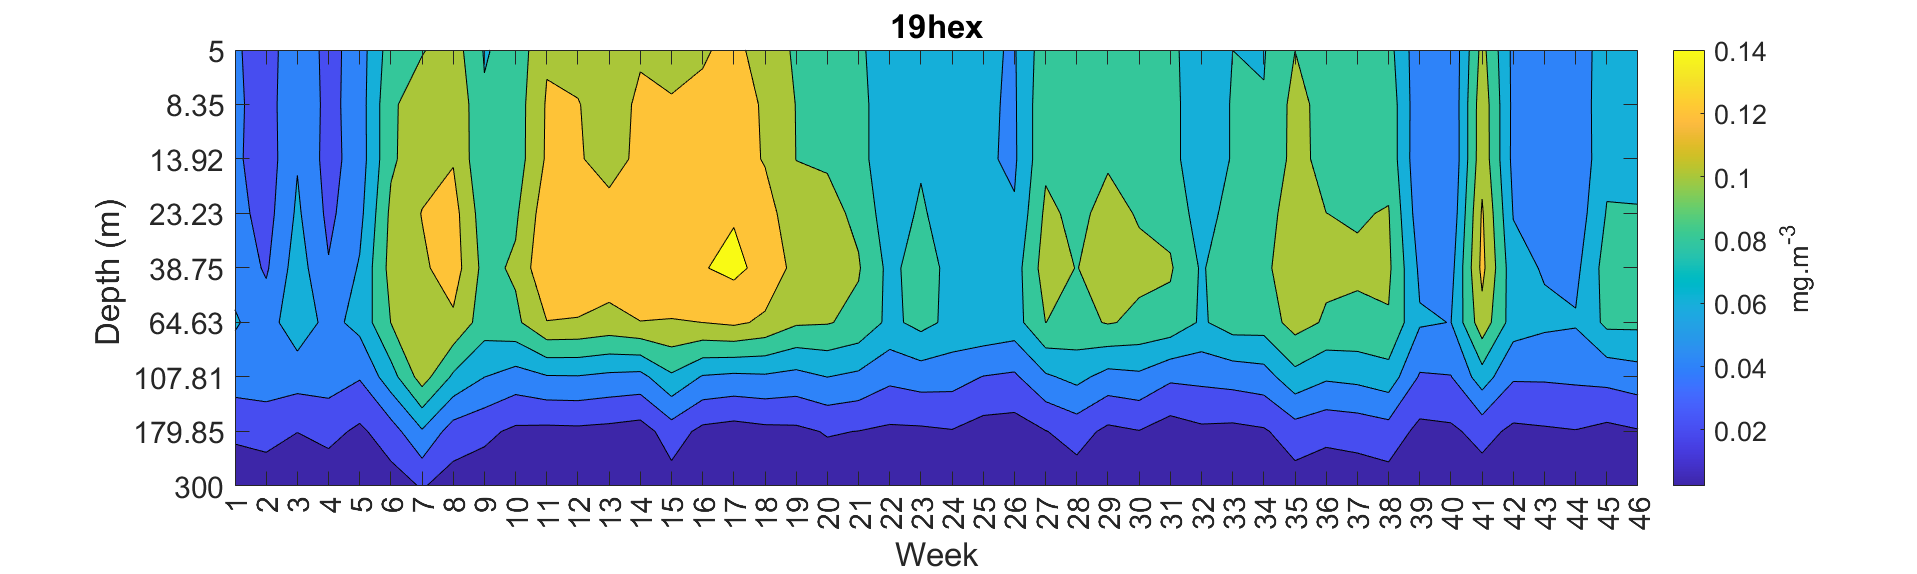


%------------HAPTOPHYTES----------------------------------------------------------------

ax(1)=figure;
contourf(x19hex')
title('19hex')
C1=colorbar;
C1.Label.String ='mg.m^-^3';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',15)
xtickangle(90)
xticks(date)
xticklabels(date)
yticks([1:9])
yticklabels(string(depths'))
set(gca,'Ydir','reverse')
xlabel("Week")
ylabel("Depth (m) ")
colormap(ax(1),parula)
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 20, 4], 'PaperUnits', 'Inches', 'PaperSize', [20, 15])
str = "19hex_temp.eps";
saveas(gcf,str,'epsc')

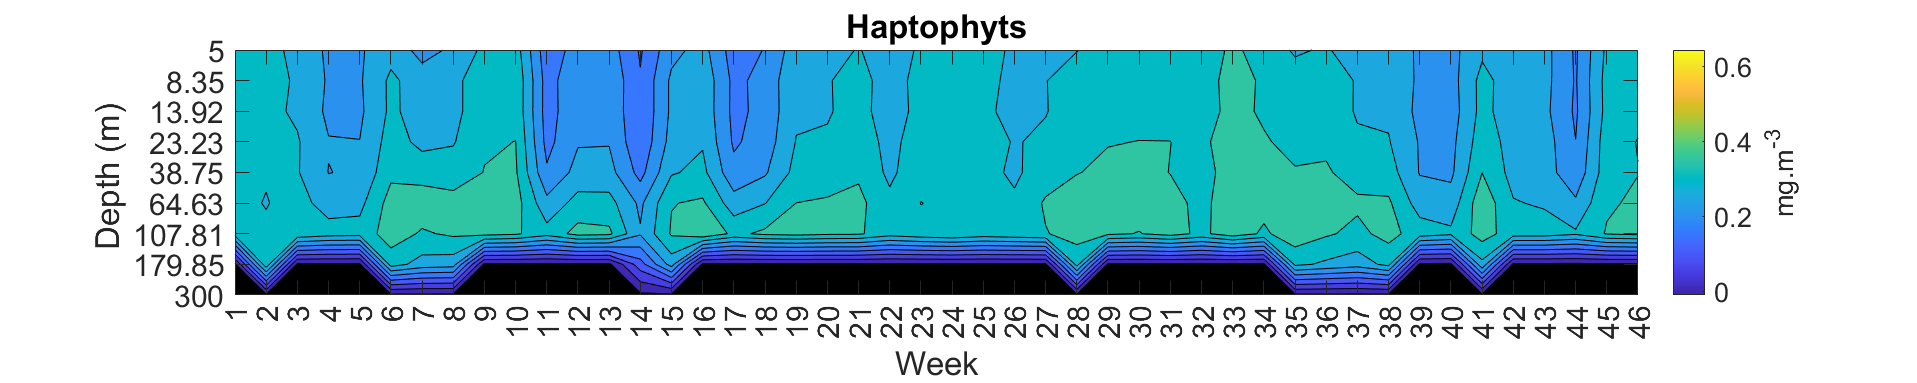


ax(2)=figure;
contourf(hapt')
title('Haptophyts')
C1=colorbar;
C1.Label.String ='mg.m^-^3';
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',15)
xtickangle(90)
xticks(date)
xticklabels(date)
yticks([1:9])
yticklabels(string(depths'))
set(gca,'Ydir','reverse')
xlabel("Week")
ylabel("Depth (m) ")
caxis([-0.01,max_all]);
colormap(ax(2),[0,0,0;parula])
set(gcf, 'Units', 'Inches', 'Position', [0, 0, 20, 4], 'PaperUnits', 'Inches', 'PaperSize', [20, 15])